## Create Layer Graph

Create the layer graph variable to contain the network layers.

mygraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([1 1 1],"Name","imageinput_2","Normalization","none")
    fullyConnectedLayer(400,"Name","fc1_dtheta")
    reluLayer("Name","relu_dtheta")
    fullyConnectedLayer(300,"Name","fc2_dtheta")];
mygraph = addLayers(mygraph,tempLayers);

tempLayers = [
    imageInputLayer([50 50 1],"Name","imageinput_1","Normalization","none")
    convolution2dLayer([10 10],2,"Name","conv1_img","Padding","same","Stride",[5 5])
    reluLayer("Name","relu_img")
    fullyConnectedLayer(400,"Name","fc1_critic")
    reluLayer("Name","relu_theta")
    fullyConnectedLayer(300,"Name","fc2_critic")];
mygraph = addLayers(mygraph,tempLayers);

tempLayers = [
    imageInputLayer([1 1 1],"Name","moment","Normalization","none")
    fullyConnectedLayer(300,"Name","fc1_moment")];
mygraph = addLayers(mygraph,tempLayers);

tempLayers = [
    additionLayer(3,"Name","addition")
    reluLayer("Name","relu")
    fullyConnectedLayer(1,"Name","finalvalue")];
mygraph = addLayers(mygraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

mygraph = connectLayers(mygraph,"fc2_dtheta","addition/in2");
mygraph = connectLayers(mygraph,"fc1_moment","addition/in1");
mygraph = connectLayers(mygraph,"fc2_critic","addition/in3");

## Plot Layers

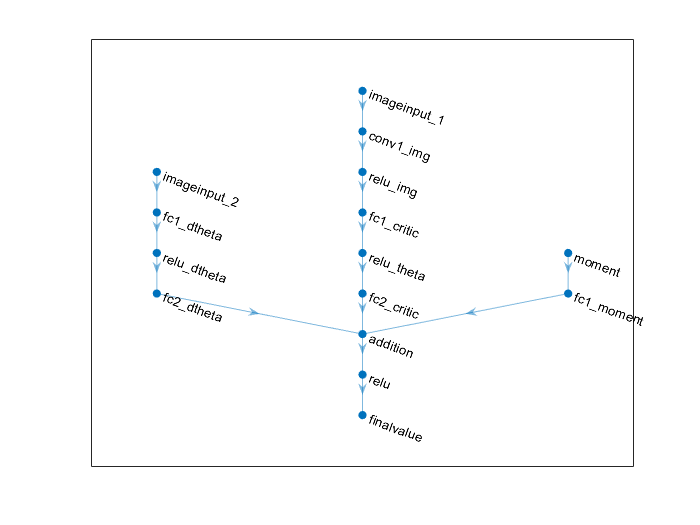

plot(mygraph);

Choices_critics = rlRepresentationOptions('LearnRate',1e-03,'GradientThreshold',1);
variable_critic = rlQValueRepresentation(mygraph,obsInfo,actInfo,...
    'Observation',{'pendImage','angularRate'},'Action',{'moment'},Choices_critics);

Unrecognized function or variable 'obsInfo'.

Choices_agents = rlDQNAgentOptions(...
    'UseDoubleDQN',false,...    
    'TargetUpdateMethod',"smoothing",...
    'TargetSmoothFactor',1e-3,... 
    'ExperienceBufferLength',1e6,... 
    'DiscountFactor',0.99,...
    'SampleTime',env.Ts,...
    'MiniBatchSize',64);
Choices_agents.EpsilonGreedyExploration.EpsilonDecay = 1e-5;

temp_agent = rlDQNAgent(variable_critic,Choices_agents);

learning_set_opts = rlTrainingOptions(...
    'MaxEpisodes',5000,...
    'MaxStepsPerEpisode',500,...
    'Verbose',false,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',-1000);

plot(env)
doTraining = false;

if doTraining
    % Train the agent.
    training_figures = train(temp_agent,env,learning_set_opts);
else
    % Load pretrained agent for the example.
    load('MATLABPendImageDQN.mat','temp_agent');
end

simulation_options = rlSimulationOptions('MaxSteps',500);
exp_1 = sim(env,temp_agent,simulation_options);

reward_sum = sum(exp_1.Reward)
